状态空间方程

Gs_ss_1 = series(Gnd_ss,Hs1*k6);
Gs_ss_2 = series(Gs_ss_1,Ds);
Gs_ss_3 = series(Gs_ss_2,k4*Hs2);
Gcl_ss = feedback(Gs_ss_3,c2d(Gp,dt,'tustin'));

传递函数

%Gs_tf_1 = k4*Hs2*G1_tfd*Hs1*k6*Gnd_tf;
%Gcl = (eye(5)+Gp_tf*Gs_tf_1)\(Gp_tf*Gs_tf_1);
Gcl_tf = tf(minreal(Gcl_ss));

112 states removed.


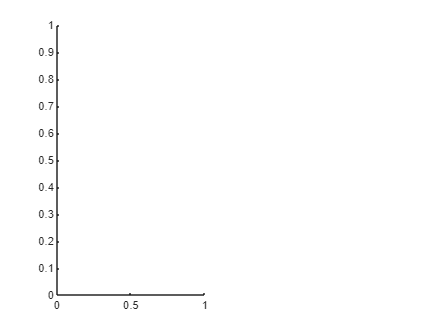


subplot(1, 2, 1);

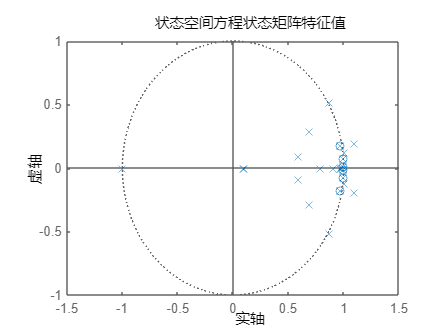

[p, z] = pzmap(Gcl_ss); % 获取极点和零点
figure;
hold on;
pzmap(Gcl_ss); % 绘制极点和零点
hold off; % 只保留极点显示
title('状态空间方程状态矩阵特征值')

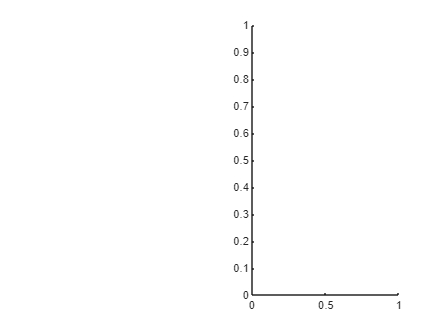

set(gcf, 'Color', 'w')

% 在右侧创建第二个子图
subplot(1, 2, 2); % 参数表示(行数, 列数, 子图编号)

[p, z] = pzmap(Gcl_tf); % 获取极点和零点

figure;
hold on;
pzmap(Gcl_tf); % 绘制极点和零点

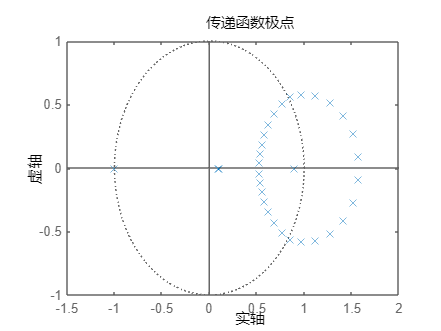

hold off; % 只保留极点显示
title('传递函数极点')

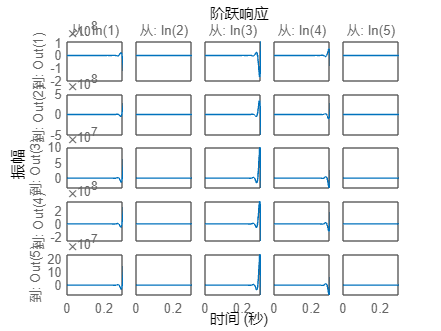

set(gcf, 'Color', 'w')


step(Gcl_ss)

bode图

%bode(Gcl_ss,Gcl_tf)

单位激励下的响应

%step(Gcl_ss,Gcl_tf)

开环

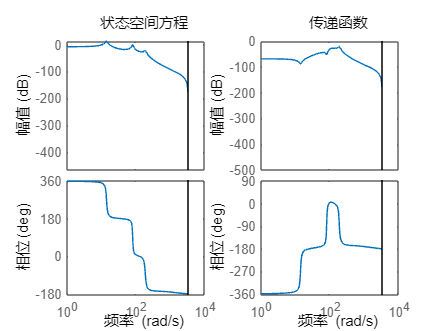

Gs_tf_1 = Hs1*k6*Gnd_tf;
%bode(series(Gnd_ss,k6),k6*Gnd_tf)
%bode(Gs_ss_1(1,1),Gs_tf_1(1,1))
%bode(Gs_ss_1,tf(Gs_ss_1))
%bode(tf(series(Hs1,Ds)),G1_tfd*Hs1)

subplot(1, 2, 1); % 参数表示(行数, 列数, 子图编号)
bode(Gs_ss_1(1,1)); % 'r'表示红色，'LineWidth'设置线宽
title('状态空间方程'); % 添加标题


% 在右侧创建第二个子图
subplot(1, 2, 2); % 参数表示(行数, 列数, 子图编号)
bode(Gs_tf_1(1,1)); % 'b'表示蓝色，'LineWidth'设置线宽
title('传递函数'); % 添加标题

set(gcf, 'Color', 'w')

Gs_tf_2 = Hs1*k6*Gnd_tf;
Gs_ss_2 = Gs_ss_1;
subplot(1, 2, 1); % 参数表示(行数, 列数, 子图编号)
bode(Gs_ss_2(1,1)); % 'r'表示红色，'LineWidth'设置线宽
title('状态空间方程'); % 添加标题

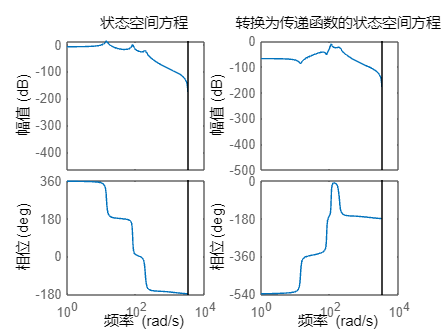



% 在右侧创建第二个子图
subplot(1, 2, 2); % 参数表示(行数, 列数, 子图编号)
bode(tf(Gs_ss_2(1,1))); % 'b'表示蓝色，'LineWidth'设置线宽
title('转换为传递函数的状态空间方程'); % 添加标题

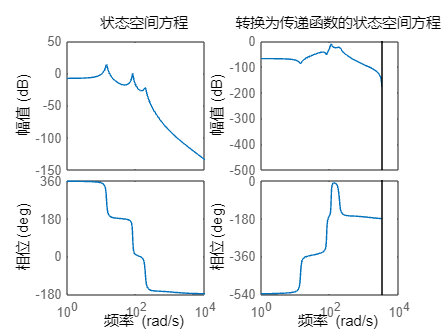

set(gcf, 'Color', 'w')


Gns_1 = Hs1*k6*Gns_ss;
Gns_2 = Hs1*k6*Gns_tf;
subplot(1, 2, 1); % 参数表示(行数, 列数, 子图编号)
bode(Gns_1(1,1)); % 'r'表示红色，'LineWidth'设置线宽
title('状态空间方程'); % 添加标题

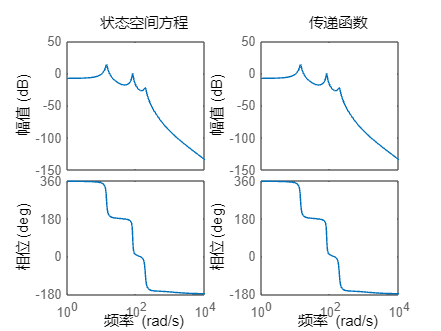



% 在右侧创建第二个子图
subplot(1, 2, 2); % 参数表示(行数, 列数, 子图编号)
bode(Gns_2(1,1)); % 'b'表示蓝色，'LineWidth'设置线宽
title('传递函数'); % 添加标题

set(gcf, 'Color', 'w')